## Ion to image (i2i)

This is a functional description of the main code functions that runs the i2i software application. This code has been verified to run in MATLAB 2022a together with the Parallel Computing Toolbox and Image Processing Toolbox.

### Load .mzML files

The readable files for this application is .mzML and can be converted with several tools. We have utilized both ProteoWizard MSConvert and ThermoRawFileParser GUI. Currently, the .mzML reader extracts metadata specific for Thermo Fisher scientific MS files and uses it for separating specific scan events. It has been tested in house on LTQ Orbitrap instruments and QExactive instruments. There are known issues with Tribrid style instruments in file conversion, however ThermoRawFileParser GUI seems to solve most of these issues.

%source_dir = 'C:\.......';
source_dir = 'E:\2022\kyle_data\mzML'

source_dir = 'E:\2022\kyle_data\mzML'

source_files = dir(fullfile(source_dir, '*.mzML'));
cd(source_dir)
[d,filters] = load_data_mzml(source_files);


The variable *d* contains all the raw centroid data and *filters* all unique scan filters. It is important that all MS experiments are conducted with the same MS method because the unique scan headers are only extracted from the first .mzML file.

*d* and a value from the *filter* variable is used to format data from a specific scan filter for further data processing.

[peak_data,time_data,tot_ion_current,NumScans] = sort_data_mzml(filters{1},d);

With the sort_data_mzml function the data is prepared for further processing. Data from the individual line scans is sorted into three data matrices, *peak_data *which stores *m/z* and intensity data, *time_data* which stores the time data for each spectrum, *tot_ion_current* which stores the total ion current in each spectrum. The *NumScans* variable is used for alignment purposes between line scans.

### Extracting *m/z* features from the data set

A target list of ions is loaded to the vaiable *MHmass*, and if putatively annotated, the annotation to the variable *names*.

%analytes_list = readtable('C:\... .xlsx')
analytes_list = readtable('E:\2022\kyle_data\mzML\analytes.xlsx');
adata = analytes_list.Var1;
MHmass = adata(1:end,1);
try
names = analytes_list.Var2;
catch
    disp('no namedata in .xlsx document')
end

The mass_intensity function extracts the  *m/z* values and intensites defined in *MHmass*. The function calculates a difference matrix between the *m/z* values in a spectrum and the values defined in *MHmass* and extracts the intensites from the closest value if its below the *cutoffppm* value.

cutoffppm = 10;
[analyte_matrix, signal_inten] = mass_intensity_dev2(MHmass,cutoffppm,peak_data,NumScans);

[~,time_out] = scanevent3(signal_inten,time_data,MHmass);

The variables analyte_matrix and is created and contains the ion intensities for the specified *m/z* values. *analyte_matrix* is a n x 1 cell array where *n* is equal to the number of analytes in MHmass. 

### Aligning features and constructing images

i2i was made for continuous ion sources, meaning that the pixel location and width is determined by the duty cycle of the mass spectrometer. For proper image reconstruction it is therefore imperative that the individual line scans are aligned. This is done by interpolating the intensity values on a time axis with 20 times more bins than the maximum number of scan events. For this we use the align_dev2 function using the *time_out* matrix for linewise interpolation. 

[aligned_matrix,time_simulated] = align_dev2(time_out,analyte_matrix);

Ion images can now be viewed using the imagesc(aligned_matrix{n}) function call. 

figure()
imagesc(aligned_matrix{1})
colormap viridis
box off
axis off

proper aspect ratio of the ion image is calculated with the aspect_ratio function

velocity = 20;
spacing = 75;
aspect = aspect_ratio(time_data,velocity,spacing)

aspect = 2.2713

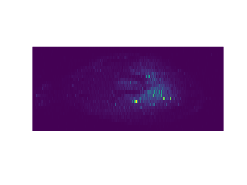

pbaspect([aspect 1 1])

Where the velocity is how fast the stage is moved, in this example 20 micrometers per second and the spacing is 75 micrometers per line scan. The pbaspect function is then used to set the dimensions.

### Normalization

Image normalization is done by dividing matrices by each other.

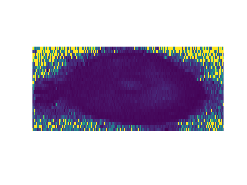

normlized_image = aligned_matrix{1}./aligned_matrix{2};
figure()
imagesc(normlized_image)
colormap viridis
box off
axis off
pbaspect([aspect 1 1])

For TIC normalization an aligned TIC matrix first need to be created.

tot_ion_current_matrix = tic_matrix(tot_ion_current,NumScans);
[tot_ion_current_aligned, ~] = align_dev2(time_out,tot_ion_current_matrix);

After which TIC normalization can be done with the TIC matrix

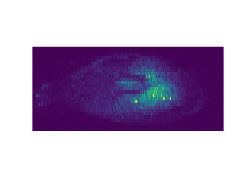

tic_normlized_image = aligned_matrix{1}./tot_ion_current_aligned{1};
figure()
imagesc(tic_normlized_image)
colormap viridis
box off
axis off
pbaspect([aspect 1 1])

## Non-targeted analysis

The application also supports non-targeted analysis. It does this by calculating a consensus m/z list in a defined subset of spectra and then creates ion images from that list. The list of consensus m/z values can be filtered in different ways to contain the desired type of data (i.e. data with high intensites, high detection frequency etc..)

The region that data will be extracted from can be programatically defined or imported from an ROI defined in the targeted analysis tab.

Here, I make an example of how the non-targeted function works so I will programatically accsess the whoel data set.

region1 = zeros(size(d,1),3)

region1 =      0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0


region1(:,1) = 1:size(d,1);
region1(:,3) = max(time_out,[],2);

The variable region1 is a n x 3 matrix where the first column denotes the line scan number, second column the start time of the ROI, and the third column the end time of the ROI. Here, I have programatically constructed the ROI to gather data from 0 to t_max for all lines.


ppmgap = 5;
min_hit = 10;
max_hit = 105;
max_int = 5E9;
min_int = 5E1;

[r1]=find_all_feat2(peak_data,ppmgap,min_hit,time_out,region1,min_int,max_hit,max_int);


The variable r1 is a peak list with 9 pieces of data and metadata

Peak group | Average m/z | something | max-mix | frequency of detection | intensity | something | somethgin | number of scans detecte in.

A list of m/z features from two different regions can also be compared against eaach other. Which enables spatially driven non-targeted data exploartion.

region2 = zeros(size(d,1),3)

region2 =      0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0


region2(:,1) = 1:size(d,1);
region2(:,3) = max(time_out,[],2)./2;

[r2]=find_all_feat2(peak_data,ppmgap,min_hit,time_out,region2,min_int,max_hit,max_int);

[uni,upreg] = compare_regions(r1,r2,min_hit,2,ppmgap);